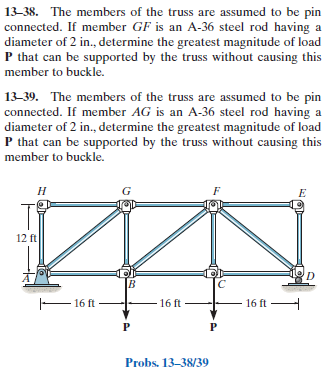

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-38P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-38P-solution-9780136022305) (problem 13-38)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-39P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-39P-solution-9780136022305) (problem 13-39)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

Pvar = sym('P', 'positive');
theta = atand(sym(12)/sym(16))*u.deg;
jointA = [0 0]*u.ft;
jointB = [16 0]*u.ft;
jointC = [32 0]*u.ft;
jointD = [48 0]*u.ft;
jointE = [48 12]*u.ft;
jointF = [32 12]*u.ft;
jointG = [16 12]*u.ft;
jointH = [0 12]*u.ft;

# member data

[D.fg D.ag] = deal(rewrite(2*u.in, u.ft));
[E.fg E.ag] = deal(rewrite(29e3*u.ksi, u.kip/u.ft^2));
[A.fg A.ag] = deal(sympi*D.fg^2/4, sympi*D.ag^2/4);
[I.fg I.ag] = deal(sympi*(D.fg/2)^4/4, sympi*(D.ag/2)^4/4);
[L.fg L.ag] = deal(16*u.ft, sqrt(sym(16)^2+sym(12)^2)*u.ft);
[sigma_yield.fg sigma_yield.ag] = deal(36*u.ksi);
Evar = sym('E');
Avar = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rd', {0 'Rdy'}, jointD);
t = t.add('concentrated', 'Pb', [0 -Pvar], jointB);
t = t.add('concentrated', 'Pc', [0 -Pvar], jointC);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('joint', 'F', jointF);
t = t.add('joint', 'G', jointG);
t = t.add('joint', 'H', jointH);
t = t.add('member', 'Fab', jointA, jointB);
t = t.add('member', 'Fbc', jointB, jointC);
t = t.add('member', 'Fcd', jointC, jointD);
t = t.add('member', 'Fef', jointE, jointF);
t = t.add('member', 'Ffg', jointF, jointG, E.fg, A.fg);
t = t.add('member', 'Fgh', jointG, jointH);
t = t.add('member', 'Fah', jointA, jointH);
t = t.add('member', 'Fag', jointA, jointG, E.ag, A.ag);
t = t.add('member', 'Fbg', jointB, jointG);
t = t.add('member', 'Fbf', jointB, jointF);
t = t.add('member', 'Fcf', jointC, jointF);
t = t.add('member', 'Fdf', jointD, jointF);
t = t.add('member', 'Fde', jointD, jointE);

# solution

[us ua ms ma ls la] = t.solve('factor');
[E.fg E.ag] = deal(rewrite(E.fg, u.ksi), rewrite(E.ag, u.ksi));
[A.fg A.ag] = deal(rewrite(A.fg, u.in), rewrite(A.ag, u.in));
[I.fg I.ag] = deal(rewrite(I.fg, u.in), rewrite(I.ag, u.in));
[D.fg D.ag] = deal(rewrite(D.fg, u.in), rewrite(D.ag, u.in));

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & \frac{64\,P}{3\,A\,\text{E}}\,\mathrm{ft}\\ \mathrm{vB} & -\frac{P\,\left(2102500\,\pi \,\mathrm{kip}+63\,A\,\text{E}\right)}{32625\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{uC} & \frac{128\,P}{3\,A\,\text{E}}\,\mathrm{ft}\\ \mathrm{vC} & -\frac{P\,\left(6554000\,\pi \,\mathrm{kip}+63\,A\,\text{E}\right)}{65250\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{uD} & \frac{64\,P}{A\,\text{E}}\,\mathrm{ft}\\ \mathrm{vD} & 0\\ \mathrm{uE} & \frac{P\,\left(3422000\,\pi \,\mathrm{kip}-63\,A\,\text{E}\right)}{87000\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vE} & 0\\ \mathrm{uF} & \frac{P\,\left(3422000\,\pi \,\mathrm{kip}-63\,A\,\text{E}\right)}{87000\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vF} & -\frac{P\,\left(5771000\,\pi \,\mathrm{kip}+63\,A\,\text{E}\right)}{65250\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{uG} & \frac{P\,\left(3422000\,\pi \,\mathrm{kip}+A\,\text{E}\right)}{87000\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vG} & -\frac{P\,\left(1711000\,\pi \,\mathrm{kip}+63\,A\,\text{E}\right)}{32625\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{uH} & \frac{P\,\left(3422000\,\pi \,\mathrm{kip}+A\,\text{E}\right)}{87000\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vH} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & \frac{4\,P}{3}\\ \mathrm{Fbc} & \frac{4\,P}{3}\\ \mathrm{Fcd} & \frac{4\,P}{3}\\ \mathrm{Fef} & 0\\ \mathrm{Ffg} & -\frac{4\,P}{3}\\ \mathrm{Fgh} & 0\\ \mathrm{Fah} & 0\\ \mathrm{Fag} & -\frac{5\,P}{3}\\ \mathrm{Fbg} & P\\ \mathrm{Fbf} & 0\\ \mathrm{Fcf} & P\\ \mathrm{Fdf} & -\frac{5\,P}{3}\\ \mathrm{Fde} & 0 \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & P & 0\\ \mathrm{Rd} & 0 & P & 0\\ \mathrm{Pb} & 0 & -P & 0\\ \mathrm{Pc} & 0 & -P & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Fbc} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Fcd} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Fef} & 0 & 0 & 0\\ \mathrm{Ffg} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Fgh} & 0 & 0 & 0\\ \mathrm{Fah} & 0 & 0 & 0\\ \mathrm{Fag} & -\frac{4\,P}{3} & -P & 0\\ \mathrm{Fbg} & 0 & P & 0\\ \mathrm{Fbf} & 0 & 0 & 0\\ \mathrm{Fcf} & 0 & P & 0\\ \mathrm{Fdf} & \frac{4\,P}{3} & -P & 0\\ \mathrm{Fde} & 0 & 0 & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & P\\ \mathrm{Rd} & P\\ \mathrm{Pb} & P\\ \mathrm{Pc} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fcd} & 0\\ \mathrm{Fef} & 0\\ \mathrm{Ffg} & 16\,P\,\mathrm{ft}\\ \mathrm{Fgh} & 0\\ \mathrm{Fah} & 0\\ \mathrm{Fag} & 0\\ \mathrm{Fbg} & 16\,P\,\mathrm{ft}\\ \mathrm{Fbf} & 0\\ \mathrm{Fcf} & 32\,P\,\mathrm{ft}\\ \mathrm{Fdf} & 48\,P\,\mathrm{ft}\\ \mathrm{Fde} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rd} & 0 & 0 & 48\,P\,\mathrm{ft}\\ \mathrm{Pb} & 0 & 0 & -16\,P\,\mathrm{ft}\\ \mathrm{Pc} & 0 & 0 & -32\,P\,\mathrm{ft} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fcd} & 0 & 0 & 0\\ \mathrm{Fef} & 0 & 0 & 0\\ \mathrm{Ffg} & 0 & 0 & -16\,P\,\mathrm{ft}\\ \mathrm{Fgh} & 0 & 0 & 0\\ \mathrm{Fah} & 0 & 0 & 0\\ \mathrm{Fag} & 0 & 0 & 0\\ \mathrm{Fbg} & 0 & 0 & 16\,P\,\mathrm{ft}\\ \mathrm{Fbf} & 0 & 0 & 0\\ \mathrm{Fcf} & 0 & 0 & 32\,P\,\mathrm{ft}\\ \mathrm{Fdf} & 0 & 0 & -48\,P\,\mathrm{ft}\\ \mathrm{Fde} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rd} & 48\,P\,\mathrm{ft}\\ \mathrm{Pb} & 16\,P\,\mathrm{ft}\\ \mathrm{Pc} & 32\,P\,\mathrm{ft} \end{array}\right)$$

# maximum load due to buckling

Pcr.buckling.fg = rewrite(sympi^2*E.fg*I.fg/L.fg^2, u.kip);
Pcr.buckling.ag = rewrite(sympi^2*E.ag*I.ag/L.ag^2, u.kip);
Pcr_buckling_fg = vpa(Pcr.buckling.fg, 3) %#ok<NASGU> 

$$Pcr\_buckling\_fg = 6.1\,\mathrm{kip}$$

Pcr_buckling_ag = vpa(Pcr.buckling.ag, 3) %#ok<NASGU> 

$$Pcr\_buckling\_ag = 3.9\,\mathrm{kip}$$

Pmax.buckling.fg = solve(abs(ms.f.m.Ffg) == Pcr.buckling.fg);
Pmax.buckling.ag = solve(abs(ms.f.m.Fag) == Pcr.buckling.ag);
Pmax_buckling_fg = vpa(Pmax.buckling.fg, 3) %#ok<NASGU> 

$$Pmax\_buckling\_fg = 4.57\,\mathrm{kip}$$

Pmax_buckling_ag = vpa(Pmax.buckling.ag, 3) %#ok<NASGU> 

$$Pmax\_buckling\_ag = 2.34\,\mathrm{kip}$$

# maximum load due to yield

Pcr.yield.fg = rewrite(solve(sigma_yield.fg == Pvar/A.fg), u.kip);
Pcr.yield.ag = rewrite(solve(sigma_yield.ag == Pvar/A.ag), u.kip);
Pcr_yield_fg = vpa(Pcr.yield.fg, 5) %#ok<NASGU> 

$$Pcr\_yield\_fg = 113.1\,\mathrm{kip}$$

Pcr_yield_ag = vpa(Pcr.yield.fg, 5) %#ok<NASGU> 

$$Pcr\_yield\_ag = 113.1\,\mathrm{kip}$$

Pmax.yield.fg = solve(abs(ms.f.m.Ffg) == Pcr.yield.fg);
Pmax.yield.ag = solve(abs(ms.f.m.Fag) == Pcr.yield.ag); 
Pmax_yield_fg = vpa(Pmax.yield.fg, 4) %#ok<NASGU> 

$$Pmax\_yield\_fg = 84.82\,\mathrm{kip}$$

Pmax_yield_ag = vpa(Pmax.yield.ag, 4) %#ok<NASGU> 

$$Pmax\_yield\_ag = 67.86\,\mathrm{kip}$$

# clean up

clear ma_f_m la_f_c ma_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
clear Pcr_buckling_fg Pcr_buckling_ag Pmax_buckling_fg Pmax_buckling_ag;
clear Pcr_yield_fg Pcr_yield_ag Pmax_yield_fg Pmax_yield_ag;
new_assum = old_assum;